# TMEM16A IHC analysis P6-P8 RT

defaultDir = 'C:\Users\Bergles Lab\Desktop\tmem16a\IHCs\P7'

defaultDir = 'C:\Users\Bergles Lab\Desktop\tmem16a\IHCs\P7'

cd(defaultDir);
% 2.5 mM K+ ACSF, P6-P8 IHC recordings, apex, room temp (22-24C)


% Calculate input resistance from IV curves, immediately after break in
% 10 mV steps from -120 mV to +50 mV
% measuring input resistance between -90 and -70 mV

[tectaTM1 time1] = loadPclampData('2020_08_19_0007.abf');

** abfload
opening 2020_08_19_0007.abf..
data were acquired in waveform fixed-length mode (clampex only)


[tectaTM2 time2] = loadPclampData('2020_08_19_0011.abf');

** abfload
opening 2020_08_19_0011.abf..
data were acquired in waveform fixed-length mode (clampex only)


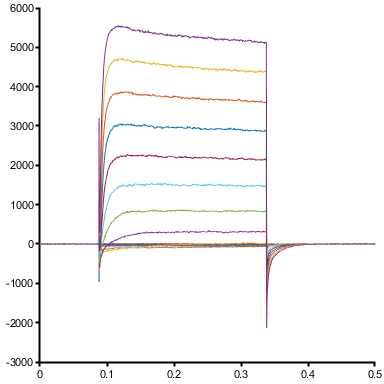

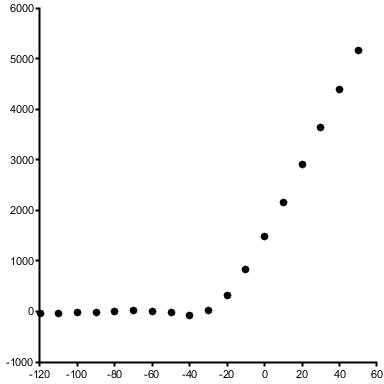

tectaTM1R = 712.3479


tectaTM1R = plotIVTM(tectaTM1,time1)

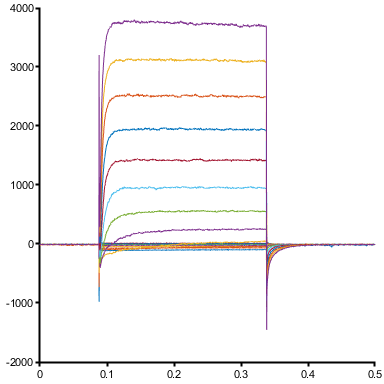

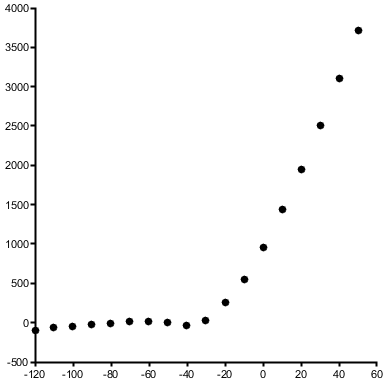

tectaTM2R = 546.1334

tectaTM2R = plotIVTM(tectaTM2,time2)


[Con1 timeCon1] = loadPclampData('2020_08_19_0024.abf');

** abfload
opening 2020_08_19_0024.abf..
data were acquired in waveform fixed-length mode (clampex only)


[Con2 timeCon2] = loadPclampData('2020_08_19_0028.abf');

** abfload
opening 2020_08_19_0028.abf..
data were acquired in waveform fixed-length mode (clampex only)


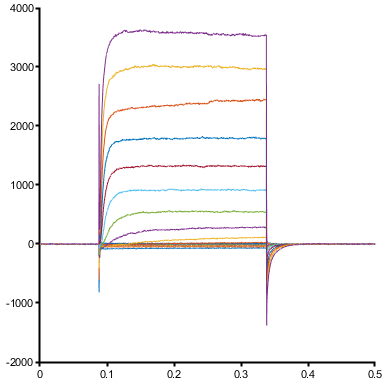

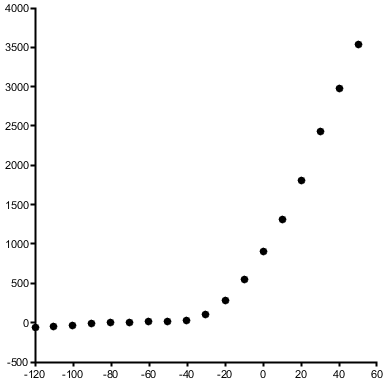

Con1R = 910.2223


Con1R = plotIVTM(Con1,timeCon1)

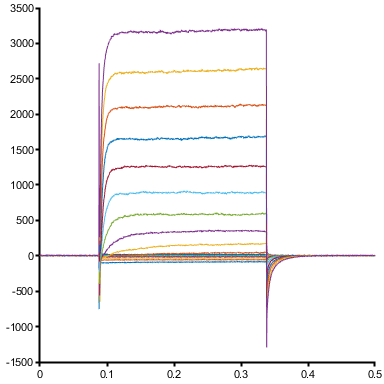

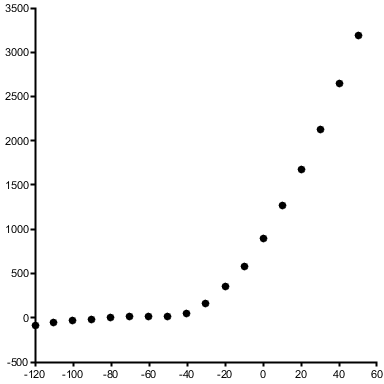

Con2R = 546.1334

Con2R = plotIVTM(Con2,timeCon2)

[tectaTM1 time1] = loadPclampData('2020_08_19_0006.abf');

** abfload
opening 2020_08_19_0006.abf..
data were acquired in gap-free mode


[tectaTM2 time2] = loadPclampData('2020_08_19_0010.abf');

** abfload
opening 2020_08_19_0010.abf..
data were acquired in gap-free mode



tectaTM1RMP = min(tectaTM1);
tectaTM2RMP = min(tectaTM2);

tectaTMRMP = [tectaTM1RMP,tectaTM2RMP]

tectaTMRMP =   -86.8256  -81.8054



[Con1 timeCon1] = loadPclampData('2020_08_19_0020.abf');

** abfload
opening 2020_08_19_0020.abf..
data were acquired in gap-free mode


[Con2 timeCon2] = loadPclampData('2020_08_19_0023.abf');

** abfload
opening 2020_08_19_0023.abf..
data were acquired in gap-free mode


[Con3 timeCon3] = loadPclampData('2020_08_19_0027.abf');

** abfload
opening 2020_08_19_0027.abf..
data were acquired in gap-free mode


%[Con4 timeCon4] = loadPclampData('2020_08_09_0023.abf');
%[Con5 timeCon5] = loadPclampData('2020_08_19_0001.abf');

Con1RMP = min(Con1);
Con2RMP = min(Con2);
Con3RMP = min(Con3);

ConRMP = [Con1RMP,Con2RMP,Con3RMP]

ConRMP =   -88.0737  -88.1409  -86.1237


% Spontaneous activity - vclamp 

[Con1 timeCon1] = loadPclampData('2020_08_19_0022.abf');

Error using abfload2 (line 144)
could not find file 2020_08_19_0022.abf

Error in loadPclampData (line 4)
    [d,si]=abfload2(datafile);

[Con2 timeCon2] = loadPclampData('2020_08_19_0026.abf');
Con1 = msbackadj(timeCon1(3000000:7500000), -Con1(3000000:7500000), 'WindowSize', 60,'StepSize',30);
Con2 = msbackadj(timeCon2(1000000:5500000), -Con2(1000000:5500000), 'WindowSize', 60,'StepSize',30);

[ConFreq1 ConAmp1 ConMax1 ConCharge1 ConPeaks1] = freqAmpIHC(-Con1, timeCon1(1:4500001)) % 15 min, nice
[ConFreq2 ConAmp2 ConMax2 ConCharge2 ConPeaks2] = freqAmpIHC(-Con2, timeCon2(1:4500001)) % 15 min

[tectaTM1 time1] = loadPclampData('2020_08_19_0012.abf'); % noisy, large drift
tectaTM1 = msbackadj(time1, -tectaTM1, 'WindowSize', 60,'StepSize',30);
[tectaTMFreq1 tectaTMAmp1 tectaTMMax1 tectaTMCharge1 tectaTMPeaks1] = freqAmpIHC(-tectaTM1, time1) % 15 min, nice


% pretty plots
% control
figure;
[Con1 timeCon1] = loadPclampData('2020_08_19_0022.abf');

** abfload
opening 2020_08_19_0022.abf..
data were acquired in gap-free mode


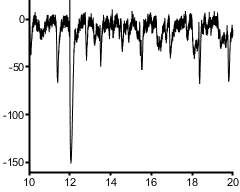

Con1 = msbackadj(timeCon1, -Con1, 'WindowSize', 60,'StepSize',30);
Con1 = medfilt1(Con1,100);
plot(timeCon1()/60,-Con1(),'k','LineWidth', 1)
ylim([-160 20]);
xlim([10 20])
figQuality(gcf,gca,[2.5 2])

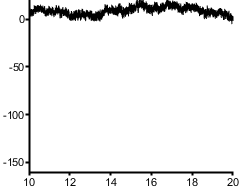


% tecta-cre; tmem16a fl/fl
figure;
tectaTM1 = medfilt1(tectaTM1,100);
plot(time1()/60,tectaTM1(),'k','LineWidth', 1)
ylim([-160 20]);
xlim([10 20])
figQuality(gcf,gca,[2.5 2])